## Data-driven discovery of differential equations

September 2020, David Braun TUM  

Throughout the course of this small project we will be applying sparse regression methods to discover the underlaying differential equations of a (measurable) system. If you are interested in more detail, check out this great paper [1] in the reference section.

#### The [Lorenz System](https://en.wikipedia.org/wiki/Lorenz_system) [2]

Let us consider a simple model for atmospheric convection, developed by the American mathematician and meterorologist Edward Lorenz in 1963. This model consists of a system of three ordinary differential equations and is known as the Lorenz system:

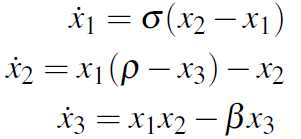

Above equations describe the properties of a two-dimensional fluid layer uniformly warmed from below and cooled from above. In particular, the equations describe the rate of change of three quantities with respect to time: $x_1$ is proportional to the rate of convection, $x_2$ to the horizontal temperature variation, and $x_3$ to the vertical temperature variation.

#### What can you expect from this project?

In the following we will explore techniques to identify nonlinear dynamics from (noisy) data without making any a-priori assumptions on the form of the governing equation. Put into simple words, our task is to find the relationship between the state derivatives ($\dot{x_1 } ,\dot{x_2 } ,\dot{x_3 }$) and the states ($x_1 ,x_2 ,x_3$). That is, we try to find the ordinary system of equations: $\dot{\mathit{\mathbf{x}}} =\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}}\right)$that describes the Lorenz dynamics.

#### How do we achieve this?

To determine the function $\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}}\right)$ from data, we start off by collecting a time history of the states  ($x_1 ,x_2 ,x_3$). Besides that, we either measure their derivatives ($\dot{x_1 } ,\dot{x_2 } ,\dot{x_3 }$) or approximate them numerically (for instance by using finite differences). Once collected, we leverage this data to come up with an optimal regressor that approximates the unknown Lorenz dynamics $\dot{\mathit{\mathbf{x}}} =\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}}\right)$. The key here, that allows us to discover the inherent structure of the underlaying differential equations is to exploit and promote sparsity within the linear regression. 

## **1. Data collection (= taking measurements)**

We start off by "taking measurements" (we will apply artificial noise to account for sensor error) of both the states and the state derivatives. 

First we set up a time grid and decide on some initial conditions x0.  

x0 = [-8;8;27];
t = linspace(0,100,10000);

Now we collect the time history of the states x by simulating the Lorenz dynamics using our x0. Here we make use of numerical integration. MATLAB provides many integration schemes. In most cases, *ode45* does the job just right.

Below command [[t,x] = ode45(odefun,t,x0)](https://de.mathworks.com/help/matlab/ref/ode45.html) integrates the system of differential equations x′=*f*(*t*,x) from t0=0 to `tf=100` with initial conditions x0. 

[~,x] = ode45(@(x,t) Lorenz(x,t),t,x0);

Let's visualize the system dynamics by plotting the time history of states.

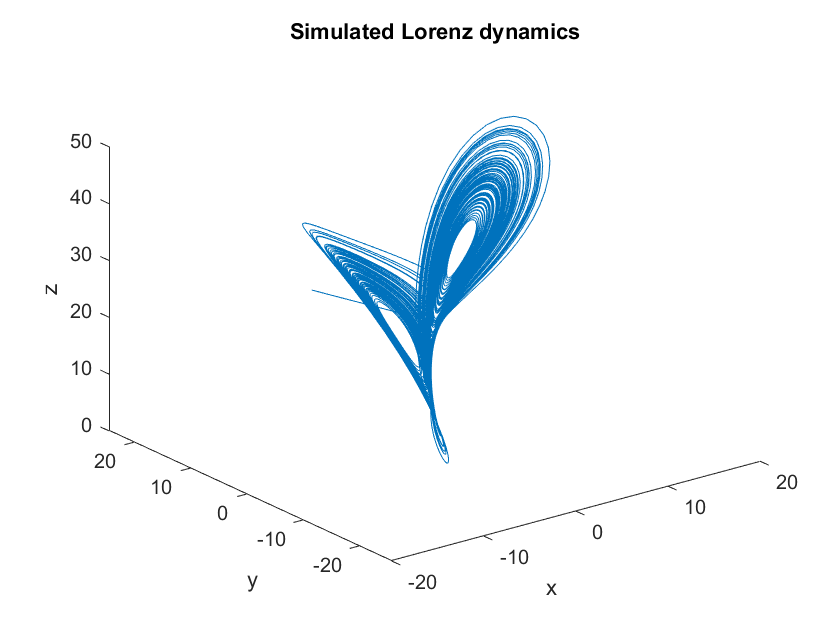

figure('Name','Lorenz system')
plot3(x(:,1),x(:,2),x(:,3))
title('Simulated Lorenz dynamics')
xlabel('x')
ylabel('y')
zlabel('z')

Mathematically speaking, given our choice of parameters, the numerical solution of the system shows deterministically chaotic behavior. Its butterfly-like trajectory has become famous and found its way into popular media. The *'butterfly effect'* stems from the real-world implications of the Lorenz attractor, i.e. that in any physical system, in the absence of perfect knowledge of the initial conditions (even the minuscule disturbance of the air due to a butterfly flapping its wings), our ability to predict its future course will always fail. [2] 

Using the time-history of states we proceed with "measuring". That is, we compute the state derivatives using the exact (unknown!) Lorenz dynamics and apply Gaussian noise (zero mean and std. deviation of one) to it.

xdot = zeros(size(x));
pd = makedist('Normal');
% The rng function controls the global stream,
% which determines how the rand, randi, randn, 
% and randperm functions produce a sequence of 
% random numbers. We set the seed for reproducibility.
rng('default');
for idx = 1:length(t)
    xdot(idx,:) = Lorenz(t(idx),x(idx,:)) + random(pd);
end

## **2) Formulate the sparse regression problem**

Having obtained all necessary data we now try to discover the underlaying dynamics of the system (from which our data stems from).

To this end we create a library of nonlinear basisfunctions of the states $\Theta \left(\mathit{\mathbf{x}}\right)$. This nonlinear feature library $\Theta \left(\mathit{\mathbf{x}}\right)$ is used to find the fewest terms needed to satisfy $\dot{\mathit{\mathbf{x}}} =\Theta \left(\mathit{\mathbf{x}}\right)\mathit{\mathbf{w}}$. The weight vector $\mathit{\mathbf{w}}$ solved for by sparse regression, denotes the relevant terms in the right-hand side of the dynamics.

The matrix $\Theta \left(\mathit{\mathbf{x}}\right)$consists of candidate functions. In general, $\Theta \left(\mathit{\mathbf{x}}\right)$ may consist of constant, polynomial, and trigonometric terms:

.

% fit data x to library of candidate basisfunctions to create Phi
Phi = fitLibrary(x); 

You can try and alter the candidates in the function "fitLibrary". Remark that you can only discover dynamics that consist of basisfunctions you put into your library. 

## **3) Solve the sparse regression problem**

The problem at hand can be formulated as the following. Given some training data (here the 'measured' xdot) we would like to obtain the optimal regression estimator${\dot{\mathit{\mathbf{x}}} }_{\textrm{est}} =\Theta \left(\mathit{\mathbf{x}}\right)\mathit{\mathbf{w}}$, where $\mathit{\mathbf{w}}$ is the vector of parameters/weights of the linear regression model, to approximate the unknown dynamics $\dot{\mathit{\mathbf{x}}} =\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}}\right)$.

That is, we seek a *sparse* solution to an overdetermined (more training observations than unknown parameters $w_i$) system with noise. *Sparsity* refers to a solution $\mathit{\mathbf{w}}$ with as many entries $w_i$ as possible, put exactly to zero.

At this point we can make use of multiple techniques. Within this project we will consider two simple approaches. 

#### a) Sequential thresholded Least-Squares algorithm

[~,m] = size(Phi);
%%% Sequential Tresholded Least-Squares algorithm %%%
weights = zeros(m,3);
% we do this for every x_dot component
for j = 1:3
    % obtain initial guess by using the ordinary least squares solution
    % ( pinv(X) provides you with the pseudoinverse of a matrix X )
    weights(:,j) = pinv(Phi)*xdot(:,j);
    
    % pick a threshold (this is a hyperparameter -> try out different values)
    threshold = 0.25;
    
    % for a fixed number of iterations:
    % - check which weights are below the threshold (magnitudewise)
    % - set those weights to zero
    % - "eliminate the respective columns from Phi"
    % - compute an updated ordinary least squares solution using only the
    %   remaining basis functions (which correspond to nonzero weights)
    % - update w
    for i = 1:100
        idx = abs(weights(:,j)) < threshold;
        weights(idx,j) = 0;
        Phi_red = Phi(:,~idx);
        weights_red = pinv(Phi_red)*xdot(:,j);
        weights(~idx,j) = weights_red;
    end
end

Let`s take some time to inspect the result. If everything worked out you'll see that most weights are set to zero. A zero weight $w_j$ implies that the j-th basis function does not participate in the underlaying dynamics. All non-zero   entries $w_i$ correspond to the candidate functions which make up the Lorenz system dynamics. Taking a closer look at the weights magnitude we find that we also approximatied the parameters sigma, rho and beta of our fluidic process.

% Note that each column represent to one of the systems state derivatives.
weights

weights =          0         0         0
   -9.9987   28.0034         0
    9.9988   -1.0018         0
         0         0   -2.6661
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


Consider the first column of the matrix "weights" (which corresponds to the derivative of $x_1$). Here we see that the second and third entry is nonzero. Checking our candidate function library those entries correspond to $x_1$ and $x_2$. That is, the sequential thresholded-LS algorithm discovered the following dynamics for $x_1$:


$$\dot{x_1 } =-9\ldotp 9987x_1 +9\ldotp 9988x_2$$
  

If we compare this result to the exact Lorenz dynamics (with sigma set to 10)

we find that our approximation has been quite good!

#### b) LASSO (least absolute shrinkage and selection operator)

The least absolute shrinkage and selection operator (LASSO) is an ℓ1-regularized regression technique that inherently promotes sparsity. For the time being, we will not dive deep into its derivation and just consult MATLAB. ([https://de.mathworks.com/help/stats/lasso.html](https://de.mathworks.com/help/stats/lasso.html))

[~,m] = size(Phi);
weights_L = zeros(m,3);
for j = 1:3
    lambda = 1e-03;
    weights_L(:,j) = lasso(Phi,xdot(:,j),'Lambda',lambda);
end

## **4) Compare the discoverd dynamics to the exact system**

Last but not least we quickly check if the discovered dynamics match the Lorenz system. To this end we plot both state histories (exact and discovered) in a single figure.

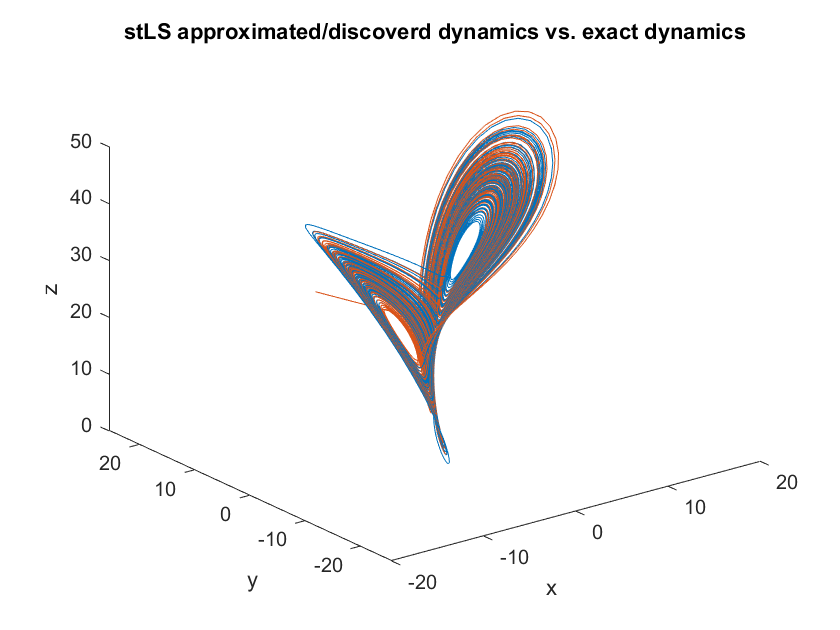

figure('Name','Evaluation of stLS')
plot3(x(:,1),x(:,2),x(:,3))
hold on
[~,xhat] = ode45(@(x,t) Lorenzhat(x,t,weights),t,x0);
plot3(xhat(:,1),xhat(:,2),xhat(:,3))
title('stLS approximated/discoverd dynamics vs. exact dynamics')
xlabel('x')
ylabel('y')
zlabel('z')

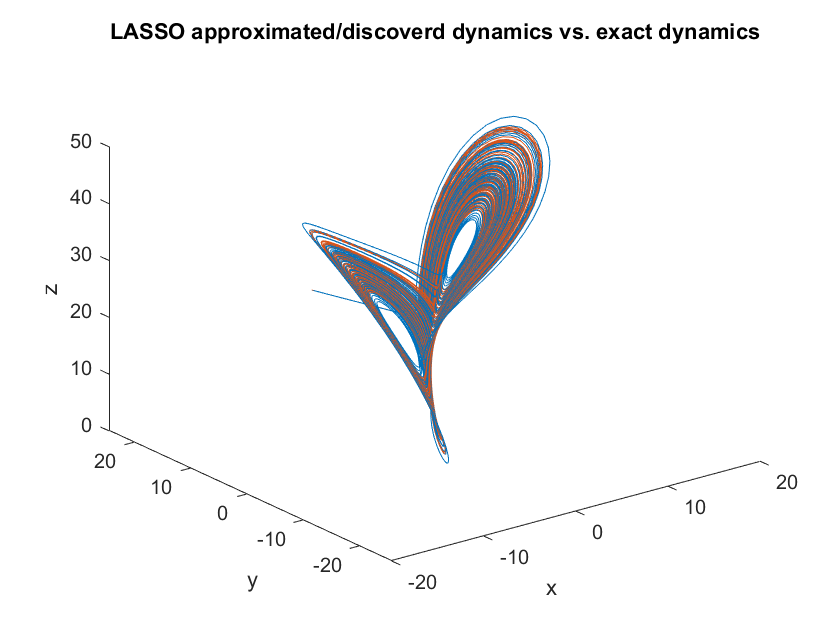

figure('Name','Evaluation of LASSO')
plot3(x(:,1),x(:,2),x(:,3))
hold on
[~,xhat_L] = ode45(@(x,t) Lorenzhat(x,t,weights_L),t,x0);
plot3(xhat_L(:,1),xhat_L(:,2),xhat_L(:,3))
title('LASSO approximated/discoverd dynamics vs. exact dynamics')
xlabel('x')
ylabel('y')
zlabel('z')

## End notes

Throughout this project, we got our hands on an exciting technique to identify nonlinear dynamic systems from (noisy) data without making a-priori assumptions on the form of the governing equations. 

#### You want to really grasp what we did here and dive deep into (sparse) regression? 

- start with learning about Linear Regression (Least Squares Method is a good way to start)

- implement a Least Squares (LS) Regression class in MATLAB (don't cheat and start from scratch)

- try and implement the sequential thresholded LS algorithm by yourself

- learn about LASSO Regression (you might need some statistics background here)

- implement a LASSO class in MATLAB (Contrary to LS we end up without a closed-form solution... Hence, the optimal set of weights has to be found with numerical optimization -> *Coordinate descent algorithm* is the keyword here)

I really hope you enjoyed this project! If you find interest in topics like this, feel free to reach out to me and I will be covering similar topics in the future. If you have any questions, doubts or feedback regarding this project, feel free to post them in the comments sections below or contact me directly via mail: [**matlab@fsmb.mw.tum.de**](javascript:linkTo_UnCryptMailto('nbjmup+nbumbcAgtnc\/nx\/uvn\/ef');)**.**

Cheers,

David

## References

[1]  [https://www.pnas.org/content/113/15/3932](https://www.pnas.org/content/113/15/3932)

[2]  [https://en.wikipedia.org/wiki/Lorenz_system](https://en.wikipedia.org/wiki/Lorenz_system)